# Lesson II.7:  Diagonalization of Small Matrices

In this lesson the procedure for diagonalizing $2\times 2$ matrices presented in Lesson II.3 is extended to $3\times 3$ matrices.  This extension entails considerable additional complexity. One reason for this added complexity is the need to factor the characteristic polynomial,

        (II.7.1)        ,

which is of degree $2$ in the $2\times 2$ case but degree 3 in the $3\times 3$ case.    While quadratic (degree 2) polynomials are factored with relative ease using the quadratic formula, cubic (degree 3) polynomials are generally factored only with heroic efforts despite the availability of a formula for the roots of cubic polynomials.  For the purposes of this course, the cubic formula is deemed impractical as a tool for factoring cubic polynomials; hence, this lesson reviews less surefire but more practical ways of dealing with cubic polynomials.    

Another, slightly less significant, reason for the added complexity in the $3\times 3$ case, is the need to solve a $3\times 3$, rather than $2\times 2$, homogeneous linear system to find the eigenvectors.   While a $3\times 3$ homogeneous system is not difficult to solve, it generally requires some arithmetic unlike the $2\times 2$ homogeneous system which is generally solvable by inspection.

While this lesson focusses on the $3\times 3$ case, we present the foundational definitions for the generally $n\times n$ case to avoid needing to repeat them in later lessons when the general case is considered.

**The basics of eigenvectors.  **The defining property of an eigenvector ${\bf v}$ of an $n\times n$ matrix *A *is that there is a number $\lambda\in{\mathbb C}$ such that

        (II.7.2a)        .

Another necessary property of an eigenvector is that it cannot be the zero vector:  

        (II.7.2b)        .

This condition can be viewed geometrically as saying that ${\bf v}$ must point in a direction (unlike ${\bf 0}$) or algebraically as ${\bf v}$ is a member of a linearly independent set (which the zero vector never is).

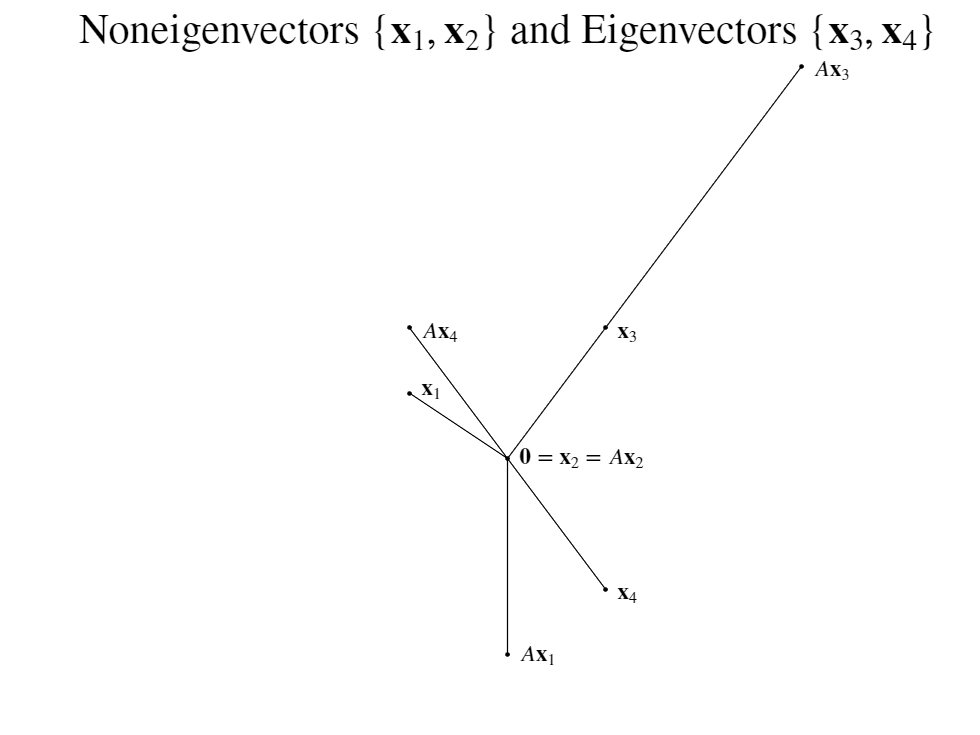

figII7a()

The relationship between the eigenvalue equation (II.7.2a) and the characteristic polynomial is an important calculation:

            
$$\matrix{
\quad&\quad&A{\bf v}&=&\lambda{\bf v} &\qquad           &\text{with} ~ {\bf v}\ne{\bf 0} \cr
\Leftrightarrow& &A{\bf v}&=&\lambda I{\bf v}&\qquad    &\text{with} ~ {\bf v}\ne{\bf 0} \cr
\Leftrightarrow& &(A-\lambda I){\bf v}&=&{\bf 0}&\qquad&\text{with} ~ {\bf v}\ne{\bf 0} \cr
\Leftrightarrow& &|A-\lambda I|&=&0&\qquad&A-\lambda I~\text{has a free variable} \cr
\Leftrightarrow& &p_A(\lambda)&=&0 \cr
}$$


Hence, an eigenvector can be found for a given value $\lambda\in{\mathbb C}$ if and only if *λ* is a root of the characteristic polynomial (i.e., an eigenvalue).   Moreover, 

        (II.7.3)        ${\bf v}\in\text{nul}(A-\lambda I)$.

Ordinarily, a basis of $\text{nul}(A-\lambda I)$ is used as the set of eigenvectors associated with *λ*.   An example will illustrate how these theoretical considerations play out in calculation of eigenvalues and eigenvectors:

**Example II.7.1:  **Find the eigenvalues and associated eigenvectors of$A=\left[\matrix{1&1&1\cr0&2&2\cr0&0&3}\right]$.

$p_A(\lambda)=(1-\lambda)(2-\lambda)(3-\lambda)$        (found easily since $A$ is triangular)


$$\underline{\lambda_1=1}:\quad A-\lambda_1I=\matrix{\bullet\cr1\cr \quad }~\left[\matrix{0&1&1\cr0&1&2\cr0&0&2}\right]\sim\matrix{\quad\cr\bullet\cr 2}~\left[\matrix{0&1&1\cr0&0&1\cr0&0&2}\right]\sim\matrix{1\cr\bullet\cr\quad}~\left[\matrix{0&1&1\cr0&0&1\cr0&0&0}\right]\sim\left[\matrix{0&1&0\cr0&0&1\cr0&0&0}\right]\quad\Rightarrow\quad {\bf v}_1=\left[\matrix{1\cr0\cr0}\right]$$



$$\underline{\lambda_2=2}:\quad A-\lambda_2I=
\matrix{\quad\cr\bullet\cr1/2}~\left[\matrix{-1&1&1\cr0&0&2\cr0&0&1}\right]\sim
\matrix{\times -1\cr\times1/2\cr\quad}~\left[\matrix{-1&1&1\cr0&0&2\cr0&0&0}\right]\sim
\matrix{-1\cr\bullet\cr\quad}~\left[\matrix{1&-1&-1\cr0&0&1\cr0&0&0}\right]\sim
\left[\matrix{1&-1&0\cr0&0&1\cr0&0&0}\right]\quad\Rightarrow\quad {\bf v}_2=\left[\matrix{1\cr1\cr0}\right]$$



$$\underline{\lambda_3=3}:\quad A-\lambda_3I=
\matrix{\times-1/2\cr\times-1\cr\quad}~\left[\matrix{-2&1&1\cr0&-1&2\cr0&0&0}\right]\sim
\matrix{-1/2\cr\bullet\cr\quad}~\left[\matrix{1&-1/2&-1/2\cr0&1&-2\cr0&0&0}\right]\sim
\left[\matrix{1&0&-3/2\cr0&1&-2\cr0&0&0}\right]\quad\Rightarrow\quad {\bf v}_3=\left[\matrix{3/2\cr2\cr1}\right]$$


MATLAB is well versed in eigenvalue and eigenvector computations.

[V, D]=eig(sym([1 1 1; 0 2 2; 0 0 3]))  

$$V = \left(\begin{array}{ccc} \frac{3}{2} & 1 & 1\\ 2 & 0 & 1\\ 1 & 0 & 0 \end{array}\right)$$

$$D = \left(\begin{array}{ccc} 3 & 0 & 0\\ 0 & 1 & 0\\ 0 & 0 & 2 \end{array}\right)$$

#### Short-cuts for computation of eigenvectors

In the computation of eigenvectors, a central operation in the final stage of the course, standard methods involve the repeated computation of bases for the null spaces of singular square matrices.    Here methods, including various short-cuts, are examined for expeditious calculations on $2\times 2$ and $3\times 3$ matrices.

**Using the singularity of the matrix.   **If $\lambda$ is an eigenvalue of the matrix $A$, then $A-\lambda I$ is necessarily singular.  Using the singularity of this matrix can simplify the computation of the null space.   Suppose that $M=A-\lambda I$ is an $n\times n$ singular matrix.    Because $M$ is singular, $\text{rank}(M)<n$ and the rows of $M$ are linearly dependent.    This means that at least one row is a linear combination of the other rows.    **Key observation**:   When a row that is a linear combination of the others, is replaced by a row of zeros, the rref is unchanged and hence the null space is unchanged.

**Example II.7.2a**.    $\text{rref}\left(\left[\matrix{1&2&3\cr4&5&6\cr 7&8&9}\right]\right)=
\text{rref}\left(\left[\matrix{1&2&3\cr4&5&6\cr 0&0&0}\right]\right)$    since     $[\matrix{7&8&9}]~=~(-1)[\matrix{1&2&3}]~+~2[\matrix{4&5&6}]$.

**Example II.7.2b**.    $\text{rref}\left(\left[\matrix{1&2&3\cr4&5&6\cr 7&8&9}\right]\right)=
\text{rref}\left(\left[\matrix{1&2&3\cr 7&8&9\cr0&0&0}\right]\right)$    since     $[\matrix{4&5&6}]~=~\frac12[\matrix{7&8&9}]~+~\frac12[\matrix{1&2&3}]$.

**Example II.7.2c**.    $\text{rref}\left(\left[\matrix{1&2&3\cr4&5&6\cr 7&8&9}\right]\right)=
\text{rref}\left(\left[\matrix{4&5&6\cr 7&8&9\cr0&0&0\cr}\right]\right)$    since     $[\matrix{1&2&3}]~=~2 [\matrix{4&5&6}]~-~1[\matrix{7&8&9}]$.

That is, when the row is known to be a linear combination of the other rows, it may be unceremoniously replaced by a row of zeros without changing the null space.   Of course, making use of this wholesale row elimination requires identification of a row that is a linear combination of the others.   In the computation of eigenvectors, the singularity of $A-\lambda I$, known from the determinant, implies at least one row is a linear combination of others.   Moreover, for $2\times 2$ and $3\times 3$ matrices, determining which rows are linear combinations of the others is generally straightforward.

For a $2\times 2$ singular matrix with two nonzero rows, each row is a multiple of the other, and either row may be eliminated from the matrix without changing the rref.

$\text{rref}\left(\left[\matrix{a&b\cr c&d}\right]\right)~=~
\text{rref}\left(\left[\matrix{a&b\cr 0&0}\right]\right)~=~
\text{rref}\left(\left[\matrix{c&d\cr0&0}\right]\right)$    if $|a|^2+|b|^2\ne0$    and    $|c|^2+|d|^2\ne 0$.

Since it is easily recognized when there are two nonzero rows in a $2\times 2$ matrix, it is generally straightforward to apply this short-cut    Happily, the $3\times 3$ case is only slightly more complicated.

For a $3\times 3$ singular matrix with three nonzero rows, the only situation where a particular row can fail to be a linear combination of the other two is if those two rows are multiples of one another.    Hence, to validly eliminate an entire row in this situation requires only to check that the remaining rows are not multiples of each other.

**Basis for the null space of a singular **$2\times 2$** matrix.    **For a nonzero $2\times 2$ singular matrix $A$, we have shown above that $A$ is row equivalent to a matrix where the first row is the only nonzero row:  $A~\sim~ \left[\matrix{u&v\cr0&0}\right]$.   A vector ${\bf v}$ in the null space (satisfying $\left[\matrix{u&v\cr0&0}\right]{\bf v}=\bf 0$) is easily found:

${\bf v}=\left[\matrix{v \cr -u}\right]$.

While this is likely not the same basis provided by the standard procedure used to generate the basic solutions of a linear system, it is a basis.  For finding eigenvectors being a basis is what matters.

**Example II.7.3a**.    A basis for $\text{nul}\left(\left[\matrix{3&-2\cr -3 &2}\right]\right)$ is $\left\{\left[\matrix{2\cr 3}\right]\right\}$.

**Example II.7.3b**.    A basis for $\text{nul}\left(\left[\matrix{0&0\cr  3 &4}\right]\right)$ is $\left\{\left[\matrix{4\cr -3}\right]\right\}$.

**Example II.7.3c**.    A basis for $\text{nul}\left(\left[\matrix{0&0\cr  0&0}\right]\right)$ is $\left\{\left[\matrix{1\cr 0}\right],~\left[\matrix{0\cr 1}\right]\right\}$.

**Basis for the null space of a singular **$3\times 3$** matrix.    **A nonzero $3\times 3$ singular matrix $A$ is row equivalent to a matrix with one or two nonzero rows:

        $A~\sim~ \left[\matrix{u&v&w\cr x&y&z\cr 0 &0 &0}\right]$    with    $|u|^2+|v|^2+|w|^2\ne0~\text{and}~|x|^2+|y|^2+|z|
^2\ne 0$         or        

        $A~\sim~ \left[\matrix{u&v&w\cr 0&0&0\cr 0 &0 &0}\right]$    with    $|u|^2+|v|^2+|w|^2\ne 0$.

In the first case (when the two nonzero rows are independent) a basis for the null space is given by the cross product of the two rows (a vector perpendicular to the two rows):

        A basis for $\text{nul}\left(\left[\matrix{u&v&w\cr x&y&z\cr 0 &0 &0}\right]\right)$    is    $\left\{\left[\matrix{
\left|\matrix{y&z\cr v&w}\right|\cr 
-\left|\matrix{x&z\cr u&w}\right|\cr
\left|\matrix{x&y\cr u&v}\right|
}\right]\right\}~=~
\left\{\left[\matrix{
yw-vz\cr 
uz-xw\cr
xv-uy
}\right]\right\}$.

Alternatively, we may complete the reduction to rref, and then

        a basis for $\text{nul}\left(\left[\matrix{1&0&a\cr 0 &1 &b\cr 0 &0 &0 }\right]\right)$    is  $\left\{\left[\matrix{-a\cr -b \cr 1}\right]\right\}$,

        a basis for  $\text{nul}\left(\left[\matrix{1&a&0\cr 0 &0 &1\cr 0 &0 &0 }\right]\right)$    is  $\left\{\left[\matrix{-a\cr 1 \cr 0}\right]\right\}$,

        a basis for  $\text{nul}\left(\left[\matrix{0&1&0\cr 0 &0 &1\cr 0 &0 &0 }\right]\right)$    is  $\left\{\left[\matrix{1\cr 0 \cr 0}\right]\right\}$.

Either of these two methods, using the cross product or full computation of the basic solutions, will produce correct results.  Which one will be the less onerous choice for a given problem is not always obvious.   Experience coming from practice is likely the best guide.

In the second case (where $\text{rank}(A)=1$), we see

        a basis for $\text{nul}\left(\left[\matrix{1&a&b\cr 0 &0 &0\cr 0 &0 &0 }\right]\right)$    is  $\left\{\left[\matrix{-a\cr 1 \cr 0}\right],\left[\matrix{-b\cr 0 \cr 1}\right]~\right\}$,

        a basis for $\text{nul}\left(\left[\matrix{0&1&a\cr 0 &0 &0\cr 0 &0 &0 }\right]\right)$    is  $\left\{\left[\matrix{1\cr 0 \cr 0}\right],\left[\matrix{0\cr -a \cr 1}\right]~\right\}$,

        a basis for $\text{nul}\left(\left[\matrix{0&0&1\cr 0 &0 &0\cr 0 &0 &0 }\right]\right)$    is  $\left\{\left[\matrix{1\cr 0 \cr 0}\right],\left[\matrix{0\cr 1 \cr 0}\right]~\right\}$,

**Example II.7.4a:**   A basis for $\text{nul}\left(\left[\matrix{1&2&3\cr 4&5&6\cr 7&8&9 }\right]\right)=
\text{nul}\left(\left[\matrix{1&2&3\cr 4&5&6\cr 0&0&0 }\right]\right)$    is  $\left\{\left[\matrix{-3\cr 6 \cr -3}\right]\right\}$.

**Example II.7.4b:**   A basis for $\text{nul}\left(\left[\matrix{3&4&1\cr 1&1&1\cr 0&-1&2 }\right]\right)=
\text{nul}\left(\left[\matrix{1&1&1\cr 0&-1&2\cr 0&0&0 }\right]\right)$    is  $\left\{\left[\matrix{3\cr -2 \cr -1}\right]\right\}$.

**Example II.7.4c:**   A basis for $\text{nul}\left(\left[\matrix{1&1&1\cr 2&2&2\cr 1&2&3 }\right]\right)=
\text{nul}\left(\left[\matrix{1&1&1\cr 1&2&3\cr 0&0&0 }\right]\right)$    is  $\left\{\left[\matrix{1\cr -2 \cr 1}\right]\right\}$.

**Example II.7.4d:**   A basis for $\text{nul}\left(\left[\matrix{1&2&3\cr 2&4&6\cr 3&6&9 }\right]\right)=
\text{nul}\left(\left[\matrix{1&2&3\cr 0&0&0\cr 0&0&0 }\right]\right)$    is  $\left\{\left[\matrix{-2\cr 1 \cr 0}\right],\left[\matrix{-3\cr 0 \cr 1}\right]~\right\}$.

**Overview of finding eigenvalues and eigenvectors.   **While the details can become quite elaborate, the process of finding eigenvalues and eigenvectors for a square matrix $A
$ is straightforward.

- Find the characteristic polynomial $p_A(\lambda)=|A-\lambda I|$ and determine its roots which are the eigenvalues of $A$.

- For each distinct eigenvalue $\lambda_\ell$, find a basis for $\text{nul}(A-\lambda_\ell I)$ which is the set of eigenvectors of $A$ associated with $\lambda_\ell$.

**Diagonalization.   **Commonly, the result of the search for eigenvalues and eigenvector for an $n\times n$ matrix $A$ described above is a list of $n$ eigenvalues $\lambda_1,\dots,\lambda_n$ and $n$ linearly independent eigenvectors ${\bf v}_1,\dots,{\bf v}_n$ satisfying

        (II.7.4a)        $A{\bf v}=\lambda_\ell {\bf v}\qquad\text{for}\qquad
\ell=1,\dots,n$.

By using the eigenvectors as the columns of a matrix and the eigenvalues as the diagonal values of a diagonal matrix, these $n$ vector equations can be written as a single matrix equation.

        (II.7.4b)        $A\left[\matrix{{\bf v}_1 &\cdots&{\bf v}_n}\right]=\left[\matrix{{\bf v}_1 &\cdots&{\bf v}_n}\right]\left[\matrix{
\lambda_1 & & \cr
& \ddots & \cr
& & \lambda_n}\right]$.

Recall that multiplying a matrix on the right by a diagonal matrix scales the columns of the matrix.   Hence,

        (II.7.4c)        $AS=SD$    where    $S=\left[\matrix{{\bf v}_1&\dots&{\bf v}_n}\right]$    and    $D=\left[\matrix{
\lambda_1 & & \cr
& \ddots & \cr
& & \lambda_n}\right]$.

Because the columns of the eigenvector matrix $S$ are linearly independent, $S$ is invertible allowing the multiplication of (II.7.4c) by $S^{-1}$ on the right.

        (II.7.5)        $A=SDS^{-1}$

This factorization of $A$ is known as a ***diagonalization*** of $A$.   

**Diagonalizing 3x3 matrices with pencil and paper.   **Owing to the somewhat intricate nature of the details of cubic polynomials, the diagonalization of $3\times 3$ can work out in a variety of ways.   Here we consider two examples in detail.

**Example II.7.5:  **Find, if possible, the diagonalization of $A=\left[\matrix{7 & 1 & -5 \cr 5 & 3 & -5 \cr 9 & 1 & -7}\right]$.

The usual starting place for the diagonalization problem is finding the characteristic polynomial with the formula

        
$$p_A(\lambda)=-\lambda^3+\text{tr}(A)\lambda^2-\text{tr}(M)\lambda+\text{det}(A)$$


where $M$is the minor matrix (formed by replacing each element of $A$ by its associated minor). Starting with the computation of the determinant is a sensible starting place:

        $\matrix{\bullet\cr 3\cr 1}~\left|\matrix{7&1&-5\cr 5 & 3 & -5 \cr 9 & 1 & -7}\right|=
\matrix{\bullet\cr 3\cr 1}~\left|\matrix{7&1&-5\cr -16 & 0 & 10 \cr 2 & 0 & -2}\right|=-\left|\matrix{-16 & 10 \cr 2 & -2}\right|=-(32-20)=-12$.

Notice entries of the second column were eliminated rather than the first to simplify the arithmetic.

        
$$\matrix{
p_A(\lambda)&=&-\lambda^3~+~(7+3-7)\lambda^2~-~\left(\left|\matrix{3&-5\cr 1 & -7}\right|+\left|\matrix{7&-5\cr 9 & -7}\right|+\left|\matrix{7&1\cr 5 & 3}\right|\right)\lambda~-~12\cr
&=&-\lambda^3~+~3\lambda^2~-~(-16-4+16)\lambda~-~12\qquad\qquad\qquad\qquad\qquad\cr
&=&-\lambda^3~+~3\lambda^2~+~4\lambda~-~12\qquad\qquad\qquad\qquad\qquad\qquad\qquad\quad\cr
}$$


With the characteristic polynomial determined, we turn to its factorization.   Any rational root will be an integer from the list $\pm1,\pm2,\pm3,\pm4,\pm6,\pm12$ (the integer factors of 12).   Here we apply synthetic division to test the candidate roots until an actual root is found.


$$\matrix{
\underline{~1~}|\quad & -1 & ~3 & 4 & -12 \cr
& & -1& 2 & ~~6  \cr
\hline
&-1&~2&6&\,-6\cr
}\qquad\qquad
\matrix{
\underline{-1~}|\quad & -1 & ~3 & ~4 & -12 \cr
& & ~1& -4 & ~~0  \cr
\hline
&-1&~4&~0&-12\cr
}\qquad\qquad
\matrix{
\underline{2~}|\quad & -1 & ~3 & ~4 & -12 \cr
& & -2& ~2 & ~12  \cr
\hline
&-1&~1&~6&~~0\cr
}\qquad\qquad$$


Hence, 2 is a root and 

        $p_A(\lambda)= (\lambda-2)(-\lambda^2+\lambda+6)=-(\lambda-2)(\lambda+2)(\lambda-3)$.

And the eigenvalues are $3,2,-2$.

The eigenvectors associated with each of these eigenvalues are then determined (using the cross product method in this example).

    
$$\underline{\lambda_1=3}:\qquad A-\lambda_1 I = \left[
\matrix{4&1&-5 \cr 5 & 0 & -5 \cr 9&1&-10
}\right] \sim
\left[
\matrix{4&1&-5 \cr 5 & 0 & -5 \cr 0&0&0
}\right]\qquad\Rightarrow\qquad {\bf v}_1=
\left[\matrix{ 
~\left|\matrix{1 & -5\cr 0 & -5}\right|\cr - \left|\matrix{4 & -5\cr 5 & -5}\right| \cr ~\left|\matrix{4 & 1 \cr 5 & 0}\right|}\right]=\left[\matrix{-5\cr -5 \cr -5}\right]\sim \left[\matrix{1\cr1\cr1}\right]$$


Multiplying an eigenvector by a nonzero constant provides another eigenvector.   That constant may be chosen to remove common factors in the components if desired.

    
$$\underline{\lambda_2=2}:\qquad A-\lambda_2 I = 
\left[ \matrix{5&1&-5 \cr 5 & 1 & -5 \cr 9&1&-9}\right] \sim
\left[ \matrix{5&1&-5  \cr 9&1&-9\cr 0&0&0}\right] 
\qquad\Rightarrow\qquad
{\bf v}_2=\left[\matrix{
\left|\matrix{1&-5\cr 1 & -9}\right|\cr
-\left|\matrix{5&-5 \cr 9 & -9}\right|\cr
\left|\matrix{5&1\cr 9&1}\right|\cr
}\right]=\left[\matrix{-4\cr 0 \cr -4      }\right]\sim \left[\matrix{1\cr0\cr1}\right]
$$


    
$$\underline{\lambda_3=-2}:\qquad A-\lambda_2 I = 
\left[ \matrix{9&1&-5 \cr 5 & 5 & -5 \cr 9&1&-5}\right] \sim
\left[ \matrix{9&1&-5 \cr 5 & 5 & -5 \cr 0&0&0}\right]
\qquad\Rightarrow\qquad
{\bf v}_3=\left[\matrix{
\left|\matrix{1&-5\cr 5 & -5}\right|\cr
-\left|\matrix{9&-5 \cr 5 & -5}\right|\cr
\left|\matrix{9&1\cr 5&5}\right|\cr
}\right]=\left[\matrix{20\cr 20 \cr 40      }\right]\sim \left[\matrix{1\cr1\cr2}\right]
$$


Hence,

        $A=SDS^{-1}$    where    $S=\left[\matrix{{\bf v}_1 & {\bf v}_2 & {\bf v}_3}\right]=\left[\matrix{1 & 1  & 1 \cr 1 & 0 & 1 \cr 1 & 1 & 2}\right]$    and    $D=\left[\matrix{\lambda_1 & 0 & 0 \cr 0 & \lambda_2 & 0 \cr 0 &0  & \lambda_3}\right]=
\left[\matrix{ 3 & 0 & 0 \cr 0 & 2 & 0 \cr  0&0&-2}\right]$.

Note that reporting a diagonalization does not necessitate the computation of $S^{-1}$unless it is explicitly required.

**Example II.7.6:  **Find, if possible, the diagonalization of $A=\left[\matrix{1 & 3 & -3 \cr 0 & 4 & 0 \cr -3 & 3 & 1}\right]$.

        
$$|A|=\left|\matrix{1&3&-3\cr 0&4&0 \cr -3 & 3 & 1}\right|=4\left|\matrix{1&-3\cr-3&1}\right|=4(1-9)=-32$$


        
$$\matrix{
p_A(\lambda)&=&-\lambda^3~+~(1+4+1)\lambda^2~-~\left(\left|\matrix{4&0\cr 3 & 1}\right|+\left|\matrix{1&-3\cr -3 & 1}\right|+\left|\matrix{1&3\cr 0 & 4}\right|\right)\lambda~-~32\cr
&=&-\lambda^3~+~6\lambda^2~-~(4-8+4)\lambda~-~32\qquad\qquad\qquad\qquad\qquad\cr
&=&-\lambda^3~+~6\lambda^2~-~32\qquad\qquad\qquad\qquad\qquad\qquad\qquad\qquad\quad\cr
}$$


Candidate roots:   $\pm1,\pm2,\pm4,\pm8,\pm16,\pm32$


$$\matrix{
\underline{~1~}|\quad & -1 & ~6 & 0 & -32 \cr
& & -1& 5 & ~~5  \cr
\hline
&-1&~5&5&-27\cr
}\qquad\qquad
\matrix{
\underline{-1~}|\quad & -1 & ~6 & ~0 & -32 \cr
& & ~1& -7 & ~~7  \cr
\hline
&-1&~7&~-7&-25\cr
}\qquad\qquad
\matrix{
\underline{2~}|\quad & -1 & 6 & ~0 & -32 \cr
& & -2& ~8 & ~16  \cr
\hline
&-1&~4&~8&-16\cr
}\qquad\qquad$$



$$\matrix{
\underline{~-2~}|\quad & -1 & ~6 & ~~0 & -32 \cr
& & ~2& -16 & ~32  \cr
\hline
&-1&~8&-16&~~0\cr
}$$


        
$$p_A(\lambda)=(\lambda+2)(-\lambda^2+8\lambda-16)=-(\lambda+2)(\lambda-4)^2$$


Actual eigenvalues:  $-2,4,4$        (4 has multiplicity 2)


$$\underline{\lambda_1=-2}:\qquad
A-\lambda_1 I = \left[\matrix{3&3&-3\cr 0&6&0\cr -3&3&3}\right]\sim\left[\matrix{3&3&-3\cr 0 & 6&0\cr 0 & 0 & 0}\right]\sim\left[\matrix{1&1&-1\cr0 & 1 & 0\cr 0 & 0 &0}\right]\sim\left[\matrix{1 &0&-1\cr 0 & 1 & 0 \cr 0 &0&0}\right]\qquad\Rightarrow\qquad {\bf v}_1=\left[\matrix{1\cr 0 \cr 1}\right]$$



$$\underline{\lambda_2=\lambda_3=4}:\qquad
A-\lambda_2 I = 
\left[\matrix{-3&3&-3\cr 0&0&0\cr -3&3&-3}\right]\sim
\left[\matrix{-3&3&-3\cr 0 & 0&0\cr 0 & 0 & 0}\right]\sim
\left[\matrix{1&-1&1\cr0 & 0 & 0\cr 0 & 0 &0}\right]
\qquad\Rightarrow\qquad {\bf v}_2=\left[\matrix{1\cr 1 \cr 0}\right]\quad\text{and}\quad
{\bf v}_3=\left[\matrix{-1\cr 0 \cr 1}\right]
$$


Hence,

        $A=SDS^{-1}$    where    $S=\left[\matrix{1 & 1  & -1 \cr 0 & 1 & 0 \cr 1 & 0 & 1}\right]$    and    $D=\left[\matrix{ -2 & 0 & 0 \cr 0 & 4 & 0 \cr  0&0&4}\right]$.

**Diagonalizing 3x3 matrices depends on some simplifying structure.  ** Because the diagonalization of $3\times 3$ matrices includes so many potentially difficult operations (most promiently the factorization of a cubic polynomial), success with diagonalization by hand generally depends on the presence and exploitation of some special property of the matrix allowing simplification.   For generally matrices, exact diagaonlization with pencil and paper is generally unreasonably complex.   For example,

A=sym([1 2 3; 4 5 6; 7 8 10])

$$A = \left(\begin{array}{ccc} 1 & 2 & 3\\ 4 & 5 & 6\\ 7 & 8 & 10 \end{array}\right)$$

[S D]=eig(A)

$$S = \begin{array}{l} \left(\begin{array}{ccc} \frac{1090}{99}+\frac{19564}{297\,\sigma_{8}}+\frac{67\,\sigma_{8}}{33}-\frac{4\,\sigma_{3}}{33} & \frac{1090}{99}-\frac{9782}{297\,\sigma_{8}}-\frac{67\,\sigma_{8}}{66}-\frac{4\,\sigma_{2}}{33}-\sigma_{5} & \frac{1090}{99}-\frac{9782}{297\,\sigma_{8}}-\frac{67\,\sigma_{8}}{66}-\frac{4\,\sigma_{1}}{33}+\sigma_{5}\\ \frac{7\,\sigma_{3}}{66}-\frac{15914}{297\,\sigma_{8}}-\frac{109\,\sigma_{8}}{66}-\frac{2023}{198} & \frac{7\,\sigma_{2}}{66}+\frac{7957}{297\,\sigma_{8}}+\frac{109\,\sigma_{8}}{132}-\frac{2023}{198}+\sigma_{4} & \frac{7\,\sigma_{1}}{66}+\frac{7957}{297\,\sigma_{8}}+\frac{109\,\sigma_{8}}{132}-\frac{2023}{198}-\sigma_{4}\\ 1 & 1 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\left(\frac{146}{9\,\sigma_{8}}+\frac{\sigma_{8}}{2}-\frac{16}{3}-\sigma_{6}\right)}^{2}\\ \sigma_{2}={\left(\frac{146}{9\,\sigma_{8}}+\frac{\sigma_{8}}{2}-\frac{16}{3}+\sigma_{6}\right)}^{2}\\ \sigma_{3}={\left(\frac{292}{9\,\sigma_{8}}+\sigma_{8}+\frac{16}{3}\right)}^{2}\\ \sigma_{4}=\frac{109\,\sqrt{3}\,\sigma_{7}\,\mathrm{i}}{132}\\ \sigma_{5}=\frac{67\,\sqrt{3}\,\sigma_{7}\,\mathrm{i}}{66}\\ \sigma_{6}=\frac{\sqrt{3}\,\sigma_{7}\,\mathrm{i}}{2}\\ \sigma_{7}=\frac{292}{9\,\sigma_{8}}-\sigma_{8}\\ \sigma_{8}={\left(\frac{9839}{54}+\frac{\sqrt{34351}\,\mathrm{i}}{6}\right)}^{1/3} \end{array}$$

$$D = \begin{array}{l} \left(\begin{array}{ccc} \frac{292}{9\,\sigma_{2}}+\sigma_{2}+\frac{16}{3} & 0 & 0\\ 0 & \frac{16}{3}-\frac{\sigma_{2}}{2}-\frac{146}{9\,\sigma_{2}}-\sigma_{1} & 0\\ 0 & 0 & \frac{16}{3}-\frac{\sigma_{2}}{2}-\frac{146}{9\,\sigma_{2}}+\sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\sqrt{3}\,\left(\frac{292}{9\,\sigma_{2}}-\sigma_{2}\right)\,\mathrm{i}}{2}\\ \sigma_{2}={\left(\frac{9839}{54}+\frac{\sqrt{34351}\,\mathrm{i}}{6}\right)}^{1/3} \end{array}$$

**Follow-up problems:**

**Problem II.7.1:  **Verify that for a square matrix $A$ that every vector in $\text{nul}(A)$ except one is an eigenvector of $A\ldotp$  What is the one exception?

**Problem II.7.2:   **Explain why every eigenvector with a nonzero eigenvalue of a square matrix must be in the column space of the matrix.

**Problem II.7.3:  **For each given matrix, determine if each of the vectors is an eigenvector of the matrix and find its eigenvalue if it is.

        
$$\text{(a)}\quad\left[\matrix{2&0\cr-1&3}\right]\qquad\left[\matrix {1\cr1}\right],~\left[\matrix {0\cr1}\right],~\left[\matrix {1\cr0}\right],~\left[\matrix {\pi\cr\pi}\right],~\left[\matrix {1\cr-1}\right],~\left[\matrix {0\cr\sqrt{2}}\right],~\left[\matrix {0\cr3+2i}\right]$$


        
$$\text{(b)}\quad\left[\matrix{0&1\cr-1&0}\right]\qquad
\left[\matrix {1\cr-1}\right],~
\left[\matrix {1\cr1}\right],~
\left[\matrix {1\cr i}\right],~
\left[\matrix {\pi \cr\pi i}\right],~\left[\matrix {i\cr-1}\right],~\left[\matrix {1-i\cr -i+1}\right],~\left[\matrix {2\cr-2i}\right]$$


        
$$\text{(c)}\quad\left[\matrix{-4&7&-3\cr-15&22&-9\cr-27&39&-16}\right]\qquad
\left[\matrix {1\cr2\cr3}\right],~
\left[\matrix {1\cr3\cr5}\right],~\left[\matrix {1\cr3\cr6}\right],~\left[\matrix {1\cr1\cr1}\right],~\left[\matrix {1\cr0\cr0}\right],~\left[\matrix {0\cr0\cr0}\right],~\left[\matrix {1\cr2i\cr-3}\right]$$


        
$$\text{(d)}\quad\left[\matrix{1&1&1&1\cr1&1&1&1\cr1&1&1&1\cr1&1&1&1}\right]\qquad
\left[\matrix {1\cr1\cr1\cr1}\right],~
\left[\matrix {1\cr1\cr-1\cr-1}\right],~
\left[\matrix {1\cr-1\cr-1\cr1}\right],~
\left[\matrix {1\cr-1\cr1\cr-1}\right],~
\left[\matrix {1\cr0\cr0\cr0}\right],~\left[\matrix {\pi\cr\pi\cr\pi\cr\pi}\right],~\left[\matrix {i^0\cr i^1 \cr i^2\cr i^3}\right]$$


**Problem II.7.4:  **For each of the following $2\times 2$ matrices, find, if possible, a linearly independent set of eigenvectors containing two vectors.

        
$$\text{(a)}\quad \left[\matrix{2 & 3 \cr 3& 2}\right]\qquad
\text{(b)}\quad \left[\matrix{3 & 2 \cr 2& 0}\right]\qquad
\text{(c)}\quad \left[\matrix{3 & 2 \cr -2& 3}\right]\qquad
\text{(d)}\quad \left[\matrix{1 & -1 \cr 2& -3}\right]$$


**Problem II.7.5:  **For each of the following $3\times 3$ matrices find, if possible, a linearly independent set of eigenvectors containing three vectors.

        
$$\text{(a)}\quad \left[\matrix{1&0&0\cr 0 & 2 & 0 \cr0&0&3}\right]\qquad
\text{(b)}\quad \left[\matrix{1&1&1\cr 0&1 & 1\cr 0 & 0 & 1}\right]\qquad
\text{(c)}\quad \left[\matrix{0&-2&-2\cr2&5&2\cr-1&-2&1}\right]\qquad$$
 
$$\text{(d)}\quad
\left[\matrix{1&1&1 \cr 1&1&1\cr 1 & 1 & 1 }\right]$$


**Problem II.7.6:**   Find the eigenvalues and corresponding eigenvectors for the general $2\times 2$ matrix:

$A=\left[\matrix{a&b\cr c &d}\right]$.

**Problem II.7.7:   **A common misconception is that a matrix having a repeated eigenvalue (i.e., an eigenvalue with multiplicity greater than 1) will not have a full set of linearly independent eigenvectors.    Show that the $3\times 3$ identity matrix has a repeated eigenvalue, but we can find 3 linearly independent eigenvectors.

**Problem II.7.8:**   Show that there is at least 1 eigenvector associated with every eigenvalue.

**Problem II.7.9:   **Find the eigenvectors for the matrices given, with the spectrum, below.

    (a)    $\left[\matrix{ 8 & 4\cr -3 & 0}\right]$        $\lambda_1=2,\qquad \lambda_2=6$                (b)    $\left[\matrix{ -3 & 0\cr 8 & 4}\right]$        $\lambda_1=-3,\qquad \lambda_2=4$

    (c)    $\left[\matrix{  4 & 8\cr  0& -3}\right]$        $\lambda_1=-3,\qquad \lambda_2=4$              (e)    $\left[\matrix{ 0 & -3\cr4 & 8}\right]$        $\lambda_1=2,\qquad \lambda_2=6$

    (f)    $\left[\matrix{1 & 2\cr -3 & 4}\right]$        $\lambda_1=\frac{5+\sqrt{15} i}{2},\qquad
\lambda_2=\frac{5-\sqrt{15} i}{2}$

    (g)    $\left[\matrix{8 & -2 & 1\cr 9 & -1 & 3\cr 6 & -2 & 3}\right]$    $\lambda_1=2,\quad
\lambda_2=3,\quad
\lambda_3=5$

    (h)    $\left[\matrix{ 0 & 1 & 1 \cr -4 & 4 & 2 \cr -2 & 1 & 3}\right]$    $\lambda_1=2,\quad\lambda_2=2,\quad \lambda_3=3$

    (i)    $\left[\matrix{13 & -6 & 2\cr 12 & -5 & 4\cr 3 & -3 & 4}\right] $    $\lambda_1=\frac{5+\sqrt{15} i}{2},\qquad
\lambda_2=\frac{5-\sqrt{15} i}{2},\qquad
\lambda_3=7$

**Problem II.7.10:**  Diagonalize, if possible, the following matrices.

    (a)    $\left[\matrix{-8 & 10 & 4 \cr -11 & 13 & 4 \cr 15 & -15 & -2}\right]$                (b)    $\left[\matrix{2 & -2 & 1 \cr 1 & 0 & 0 \cr 0 & 0 & 1}\right]$

function figII7a()
figure
hold on
title('Noneigenvectors $\{ {\bf x}_1,{\bf x}_2 \}$ and Eigenvectors $\{ {\bf x}_3,{\bf x}_4 \}$','Interpreter','latex','FontSize',18)
axis([-3 3 -1.5 3])
axis square
axis off
A=[1 2; 2 1];
x1=[-1; 1/2];
x2=[0; 0];
x3=[1;1];
x4=[1;-1];
vdot(x1)
text(x1(1)+0.1,x1(2)+0.03,'${\bf x}_1$','Interpreter','latex')
vdot(x2)
text(x2(1)+0.1,x2(2),'${\bf 0}={\bf x}_2=A{\bf x}_2$','Interpreter','latex')
vdot(x3)
text(x3(1)+0.1,x3(2)-0.03,'${\bf x}_3$','Interpreter','latex')
vdot(x4)
text(x4(1)+0.1,x4(2)-0.03,'${\bf x}_4$','Interpreter','latex')
y1=A*x1;
y2=A*x2;
y3=A*x3;
y4=A*x4;
vdot(y1)
text(y1(1)+0.1,y1(2),'$A{\bf x}_1$','Interpreter','latex')
vdot(y2)
vdot(y3)
text(y3(1)+0.1,y3(2)-0.03,'$A{\bf x}_3$','Interpreter','latex')
vdot(y4)
text(y4(1)+0.1,y4(2)-0.03,'$A{\bf x}_4$','Interpreter','latex')
end

function vdot(x)
plot(x(1),x(2),'.k')
plot([0 x(1)],[0 x(2)],'k')
end